%Clear everything
close all
clc
clear
clear('cam')

%start cam and take a picture
webcamlist;

ans = 2×1 cell array
    {'Integrated Webcam'}
    {'WEB CAM'          }


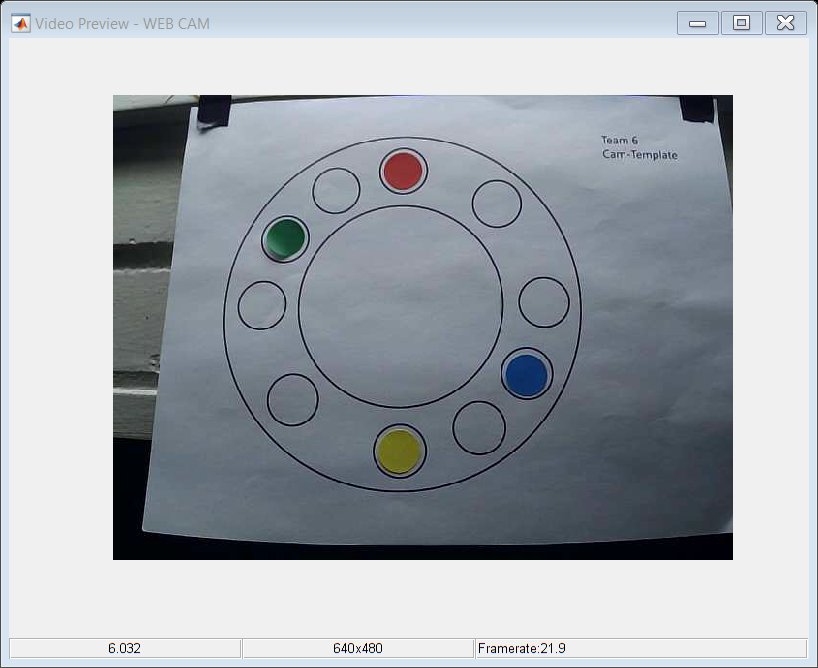

cam = webcam(2);
cam.Resolution = '640x480';
preview(cam);
pause(5);
img = snapshot(cam);
imshow(img)


%Find circles
[centers, radii, metric] = imfindcircles(img,[15 30]);

%add blue circles around the found circles
viscircles(centers, radii,'EdgeColor','b');

%find center of the circles
%circCenter = mean(centers)
circCenterX = (max(centers(:,1))+min(centers(:,1)))/2;
circCenterY = (max(centers(:,2))+min(centers(:,2)))/2;
circCenter = [circCenterX, circCenterY];

circCenter =   299.8813  223.5509



%draw a red circle at the center
viscircles(circCenter, 10, 'EdgeColor', 'r');

%preassign memory for variables (helps runtime speed)
angles = zeros(1,length(centers(:,1)));
circColors = zeros(1,length(centers(:,1)),3);

%Make a mesh grid for image
[x, y] = meshgrid(1:size(img,2), 1:size(img,1));

for i = 1:length(centers(:,1))
    %draw lines to all of the circles
    line([circCenter(1) centers(i,1)], [circCenter(2) centers(i,2)]);
    %calculate angle in radians of each of the circles
    angles(i) = atan2(centers(i,2)-circCenter(2),centers(i,1)-circCenter(1));
    %create circle mask to only look at inside 50% of circle
    mask = (x-centers(i,1)).^2 + (y-centers(i,2)).^2 < floor(radii(i)*0.5).^2;
    %get average r, g, and b of circle inside
    circColors(1,i,:) = sum(sum(double(img) .* mask)) / sum(mask(:));
end

%convert the angle from radians to degrees
degAngles = rad2deg(angles);

degAngles =    91.3025   -3.5882   56.8929  -48.7778   26.7568  -89.8283 -119.0639 -148.4423  141.1012 -177.5785


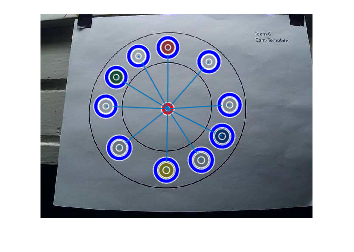


%preallocate for new color array
circTrip = zeros(length(circColors(1,:,1)),3);
for i = 1 : length(circColors(1,:,1))
    %make rgb trips
    circTrip(i,:) = [circColors(1,i,1), circColors(1,i,2), circColors(1,i,3)];
end
%make half radius
newRad = radii ./ 2;
%make rgb trips to matlab form
newColors = circTrip ./ 255;

for i = 1 : length(circColors(1,:,1))
    %print circles to picture
    viscircles(centers(i,:), newRad(i),'Color', newColors(i,:));
end